%todo dodac ograniczenie na ilosc iteracji

% usuwanie wartosci skrajnych
%   [wart indx] = max(cond_sym(:,rozmiar));
%   iteracje_sym_bezprzes(indx,rozmiar) = 0;

% % wyznaczanie pierw f. kwadratowej
% function [x1 x2] = pierw_f_kwadratowej(mala_macierz)
%     a = 1;
%     b = -(mala_macierz(1,1)+mala_macierz(2,2));
%     c = (mala_macierz(1,1)*mala_macierz(2,2))-(mala_macierz(2,1)*mala_macierz(1,2));
%     
%     x1 = (-b + sqrt(b*b - 4*a*c))/(2*a);
%     x2 = (-b - sqrt(b*b - 4*a*c))/(2*a);
%     if abs(x2) > abs(x1)
%         x1 = x2;
%     end
%    %drugi pierwiastek ze wzorów Viete'a
%     x2 = ((-b)/a) - x1;
% end

start

clc;
clear;
x = linspace(0,15,100);

przedzialy poczatkowe

przedzialy = [6 8; 8.3 10; 12 15];

dokladnosc_zer = 0.001;
wielkosc_przedzialu = 0.001;

for i=1:3
    %wybor i-tego przedzialu
    sprawdzenie_przedzialu(przedzialy(i,:));
end

wykres

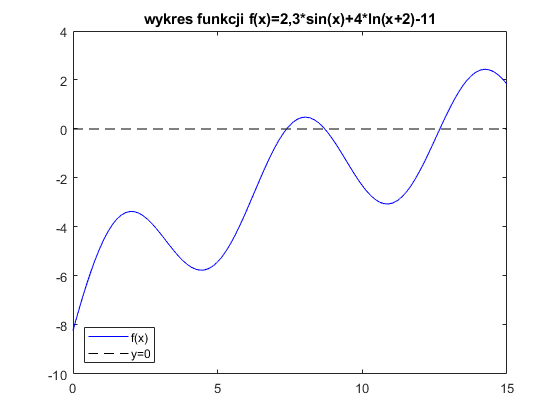

figure
y = wartosc_funkcji(x);
y2 = wartosc_funkcji(przedzialy);
plot(x,y,'b-',[0 15], [0 0], 'k--');
legend({'f(x)', 'y=0'},'Location','southwest');
title('wykres funkcji f(x)=2,3*sin(x)+4*ln(x+2)-11');

oszacowanie miejsc zerowych na podstawie rysunku (skrypt prof Tatjeskiego mowi, zeby estymowac na poodstawie rysunku)

% wartosc_funkcji(7.25)
% wartosc_funkcji(8)
% wartosc_funkcji(9)
% wartosc_funkcji(12.5)

porownanie

x_bisekcja = bisekcja(przedzialy, dokladnosc_zer, wielkosc_przedzialu)

x_bisekcja =     7.3799
    8.7042
   12.6775


x_sieczne = met_siecznych(przedzialy, dokladnosc_zer, wielkosc_przedzialu)

x_sieczne =     7.3802
    8.7041
   12.6774


x_styczne = met_stycznych(przedzialy, dokladnosc_zer, wielkosc_przedzialu)

x_styczne =     7.3794
    8.7046
   12.6774


y_bisekcja = wartosc_funkcji(x_bisekcja)

y_bisekcja = 	1.0e+-3 *

    0.5894
    0.0635
    0.3097


y_sieczne = wartosc_funkcji(x_sieczne)

y_sieczne = 	1.0e+-3 *

    0.9862
    0.2992
    0.0261


y_styczne = wartosc_funkcji(x_styczne)

y_styczne = 	1.0e+-3 *

   -0.1670
   -0.4659
   -0.0000



fprintf('najwiekszy blad zera przy metodzie bisekcji %f\n', najwieksze_zero(x_bisekcja));

najwiekszy blad zera przy metodzie bisekcji 0.000589


fprintf('najwiekszy blad zera przy metodzie siecznych %f\n', najwieksze_zero(x_sieczne));

najwiekszy blad zera przy metodzie siecznych 0.000986


fprintf('najwiekszy blad zera przy metodzie stycznych %f\n', najwieksze_zero(x_styczne));

najwiekszy blad zera przy metodzie stycznych 0.000466


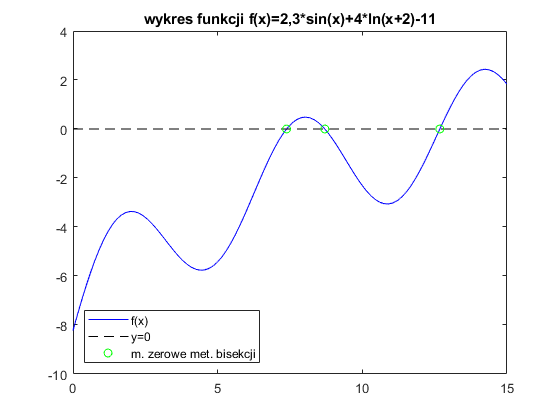


figure
plot(x,y,'b-',[0 15], [0 0], 'k--', x_bisekcja, wartosc_funkcji(x_bisekcja), 'go');
legend({'f(x)', 'y=0', 'm. zerowe met. bisekcji'},'Location','southwest');
title('wykres funkcji f(x)=2,3*sin(x)+4*ln(x+2)-11');

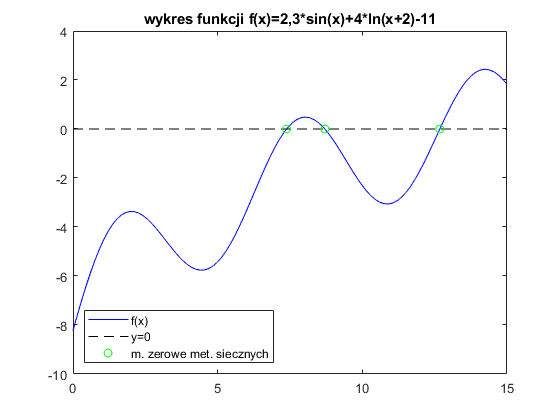


plot(x,y,'b-',[0 15], [0 0], 'k--', x_sieczne, wartosc_funkcji(x_sieczne), 'go');
legend({'f(x)', 'y=0', 'm. zerowe met. siecznych'},'Location','southwest');
title('wykres funkcji f(x)=2,3*sin(x)+4*ln(x+2)-11');

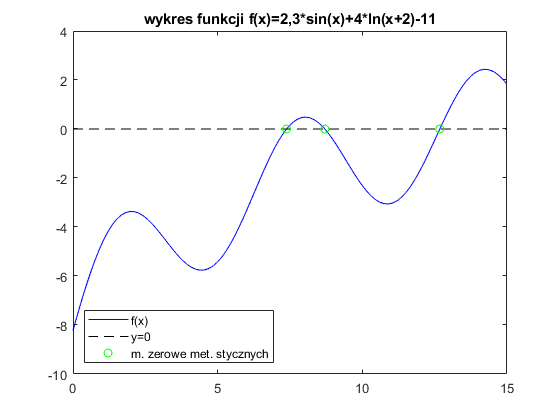


plot(x,y,'b-',[0 15], [0 0], 'k--', x_styczne, wartosc_funkcji(x_styczne), 'go');
legend({'f(x)', 'y=0', 'm. zerowe met. stycznych'},'Location','southwest');
title('wykres funkcji f(x)=2,3*sin(x)+4*ln(x+2)-11');

**funkcje pomocnicze glowne**

**1. metoda bisekcji**

function x = bisekcja(przedzialy, dokladnosc_zer, wielkosc_przedzialu)
    ilosc_pierwiastkow = size(przedzialy,1);
    x = zeros(ilosc_pierwiastkow);
    x = wektor(x);
    for i = 1:ilosc_pierwiastkow
        c = 0;
        while (abs(wartosc_funkcji(c))>dokladnosc_zer | (przedzialy(i,2)-przedzialy(i,1))>wielkosc_przedzialu)
            [c przedzialy(i,:)] = polowienie_przedzialu(przedzialy(i,:));
        end
        x(i) = c;
    end
end

polowienie przedzialow dla metody bisekcji

function [c nowy_przedzial] = polowienie_przedzialu(przedzial)
    c = (przedzial(1)+przedzial(2))/2;
    if(sprawdzenie_przedzialu([przedzial(1) c]) == 1)
        nowy_przedzial = [przedzial(1) c]; 
    else
        nowy_przedzial = [c przedzial(2)];
    end
end

**2. metoda siecznych**

function x = met_siecznych(przedzialy, dokladnosc_zer, wielkosc_przedzialu)
    ilosc_pierwiastkow = size(przedzialy,1);
    x = zeros(ilosc_pierwiastkow);
    x = wektor(x);
    for i = 1:ilosc_pierwiastkow
        c = 0;
        while (abs(wartosc_funkcji(c))>dokladnosc_zer | (przedzialy(i,2)-przedzialy(i,1))>wielkosc_przedzialu)
            [c przedzialy(i,:)] = nowy_sieczny_przedzial(przedzialy(i,:), c);
        end
        x(i) = c;
    end
end

zmniejszenie przedzialow dla metody siecznych

function [d nowy_przedzial] = nowy_sieczny_przedzial(przedzial, c)
    d = wyznacz_zero_f_liniowej(przedzial);
    if(przedzial(2) == c)
        nowy_przedzial = [d przedzial(2)]; 
    else
        nowy_przedzial = [przedzial(1) d]; 
    end
end

wyznaczenie zera f. liniowej wyznaczonej na podstawie punktow z koncow przedzialu na podstawie wyliczonego analitycznie wzoru

function c = wyznacz_zero_f_liniowej(przedzial)
    x1 = przedzial(1);
    x2 = przedzial(2);
    y1 = wartosc_funkcji(x1);
    y2 = wartosc_funkcji(x2);
    c = (x2*y1-x1*y2)/(y1-y2);
end

**3. metoda stycznych**

function x = met_stycznych(przedzialy, dokladnosc_zer, wielkosc_przedzialu)
    ilosc_pierwiastkow = size(przedzialy,1);
    x = zeros(ilosc_pierwiastkow);
    x = wektor(x);
    for i = 1:ilosc_pierwiastkow
        c = 0;
        pierwotny_przedzial = przedzialy(i,:);
        while (abs(wartosc_funkcji(c))>dokladnosc_zer)
            [c przedzialy(i,:)] = nowy_przedzial_sieczny(przedzialy(i,:), pierwotny_przedzial);
        end
        x(i) = c;
    end
end

zmniejszenie przedzialow dla metody stycznych

function [d nowy_przedzial] = nowy_przedzial_sieczny(przedzial, pierwotny_przedzial)
    d = nowy_punkt_sieczny(przedzial(1));
    if(d >= pierwotny_przedzial(1) & d <= pierwotny_przedzial(2))
        nowy_przedzial = [d przedzial(2)];
    else
        disp(przedzial);
        disp(d);
        error('Error. \nPunkt poza przedzialem');
    end
end

wyznaczenie miejsca zerowego na podstawie pochodnej oraz poprzedniego punktu

function x0 = nowy_punkt_sieczny(x)
    m = wartosc_pochodnej(x);
    y = wartosc_funkcji(x);
    x0 = (m*x-y)/m;
end

wyznaczenie pochodnej dla podanych x-ow

function y = wartosc_pochodnej(x)
    y = 23*cos(x)/10+4/(x+2);
end

**funkcje pomocnicze dodatkowe**

wyznaczenie wyjsc dla podanych x-ow i zadanej funkcji

function y = wartosc_funkcji(x)
    [temp rozmiar_x] = size(x);
    if rozmiar_x == 1
        x = x';
        rozmiar_x = temp;
    end
    y = zeros(rozmiar_x);
    y = y(:,1);
    for i = 1:rozmiar_x
        y(i,1) = 2.3*sin(x(1,i))+4*log(x(1,i)+2)-11;
    end
end

sprawdzenie czy w podanym przedziale jest miejsce zerowe

function result = sprawdzenie_przedzialu(przedzial)
    if wartosc_funkcji(przedzial(1))*wartosc_funkcji(przedzial(2)) < 0
        result = 1;
    else
        result = 0;
    end
end

wartosc najwiekszego bledu

function y = najwieksze_zero(x)
    y = max(abs(wartosc_funkcji(x)));
end

funkcja wektoryzujaca macierz diagonalna

function w = wektor(A)
    rozmiar = size(A);
    for i = 1:rozmiar
        w(i,1) = A(i,i);
    end
end

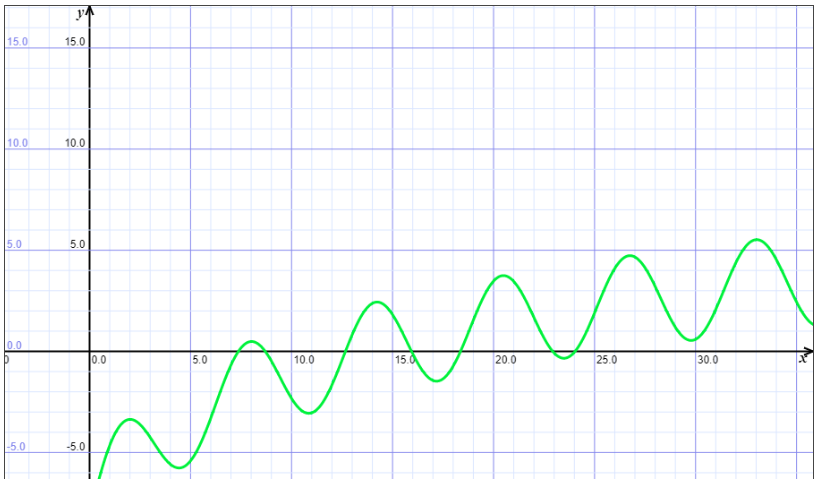

[https://www.matemaks.pl/program-do-rysowania-wykresow-funkcji.html](https://www.matemaks.pl/program-do-rysowania-wykresow-funkcji.html)

2,3*sin(x)+4*log(x+2)-11